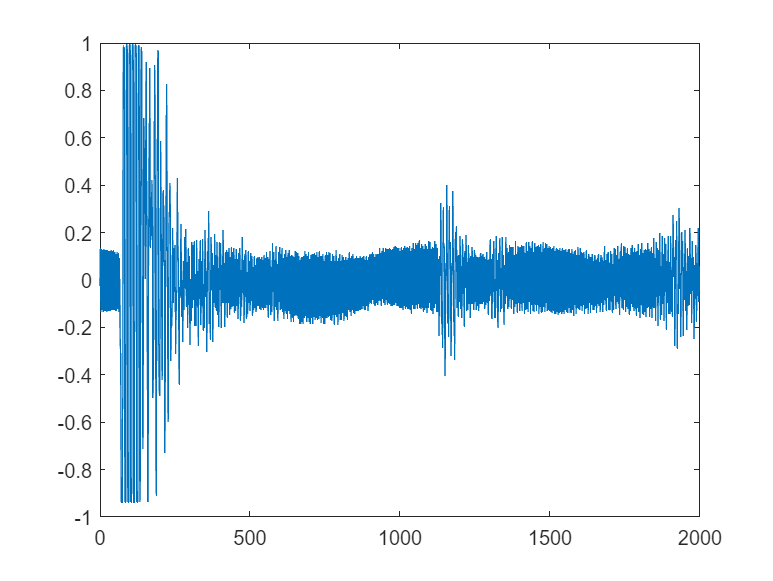

load test_data.mat -mat
load fils.mat -mat
f1 = figure;
figure(f1);
range = 0:1:length(data(:,1))-1;
deb = zeros(2000, 4);

nyq = 100000/2;
deb(:,1) = data(:,1) - mean(data(:,1));
deb(:,2) = data(:,2) - mean(data(:,2));
deb(:,3) = data(:,3) - mean(data(:,3));
deb(:,4) = data(:,4) - mean(data(:,4));
fil1 = filter(Num1, 1, deb(:,2));
fil2 = filter(Num2, 1, fil1);
%plot(range, deb(:,2))
plot(range, deb(:,2))

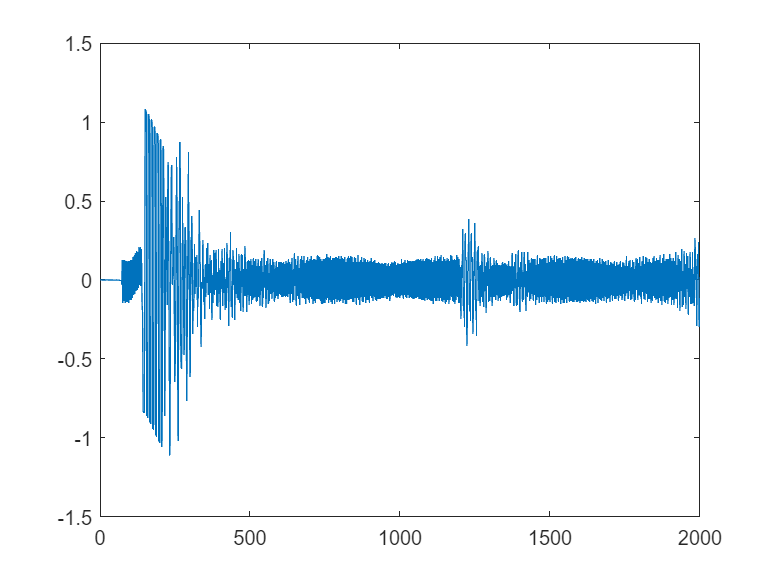

f3 = figure;
figure(f3);
plot(range, fil1)

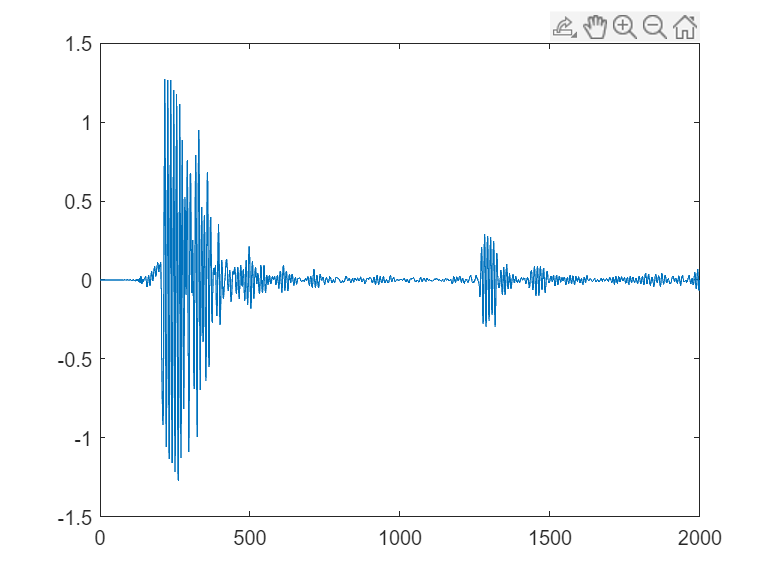

%hold on
f2 = figure;
figure(f2);
plot(range, fil2)

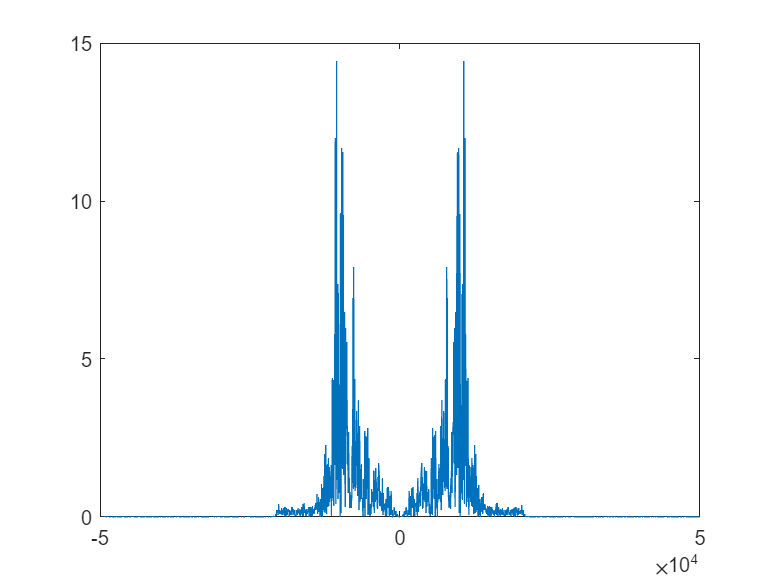

f4 = figure;
figure(f4);
wndw = window(@hann, length(data(:,1)));
wndd = fil2.*wndw;
fft_r = fft(wndd);
fft_s = fftshift(fft_r);
%plot(-nyq:(2*nyq/(length(fft_s)-1)):nyq,20*log10(abs(real(fft_s))))
plot(-nyq:(2*nyq/(length(fft_s)-1)):nyq,abs(real(fft_s)))